**Submission: **Convert this document to a pdf file for submission

**提交**：将本文档转化为pdf文件提交到gradescope

**PART 1    Simple Introdution**

(10 points)1. $\mathrm{y}=e^{x+x^2 }$ and $\mathrm{y}=\sin \left(x\right)\cos \left(x\right)$,x is from -5 to 5. Please plot the figure in a **1*2 **figure .(Hint: use *subplot. *Both numerical method and symbolic method is ok)

定义$\mathrm{y}=e^{x+x^2 }$ 和 $\mathrm{y}=\sin \left(x\right)\cos \left(x\right)$，x的定义域为[-5.5]，并在在**1*2**的图中画出两个函数。（提示：使用*subplot*来画1*2的图。数值法和符号法都可行）

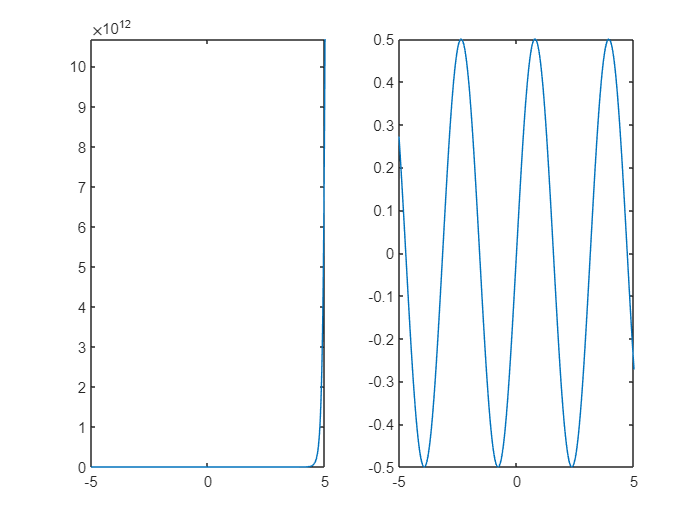

clear;clf;
syms x;
y1 = exp(x+x^2);
y2 = sin(x)*cos(x);
subplot(1,2,1);fplot(y1,[-5,5])
subplot(1,2,2);fplot(y2,[-5,5])

(8 points)2. Let a =17.2, b = 4. Please calculate the following formulas and **show** the results.

令a =17.2, b = 4。 请计算出c与d的值并展示出结果。


$$c=\;\sqrt[3]{a+9\ldotp 8}$$



$$d=100\cdot \sqrt{5b+16}$$


clear;clf;
a = 17.2;
b = 4;
c = (a + 9.8)^(1/3);
d = 100*(5*b + 16)^(1/2);
disp(c);disp(d);

     3

   600



(10 points)3. Please solve the following equations.

请求解以下方程组


$$\left\lbrace \begin{array}{c}
3x+2y-z=10\\
-x+3y+2z=5\\
x-y-z=-1
\end{array}\right.$$


a. changing to the matrix form.

用矩阵表示该方程组系数

b. using matrix operation to solve. (**Hint**:use A/B or A\B)

请使用矩阵方法求解该方程组

clear;clf;
A = [3 2 -1;-1 3 2;1 -1 -1];
B = [10;5;-1];
x = A\B;
disp(A);disp(B);disp(x);

     3     2    -1
    -1     3     2
     1    -1    -1

    10
     5
    -1

   -2.0000
    5.0000
   -6.0000



(12 points) 4. Find the prime number between 1 and 100 **by using loop and branching**. (*primes* is not allowed)

找到1到100之间的质数并显示结果。（函数*primes*不被允许使用）

clear;clf;
for i = 2 : 100
    for j = 2 : 10
        if (~mod(i,j))
            break
        end
    end
    if (j > (i/j))
        disp(i)
    end
end

     2

     3

     5

     7

    11

    13

    17

    19

    23

    29

    31

    37

    41

    43

    47

    53

    59

    61

    67

    71

    73

    79

    83

    89

    97



**PART 2     File Loading and Analysis** 

(24 points)5. Fetching external data( Do not change the value you obtain)

外部数据获取（不要修改获取的数据的值）

a. Load file Array.mat, display vector and matrix

读入Array.mat，并显示其中的两个变量vector及matrix

b. Assign the 3rd, 6th, 9th, and 12th digits to a vectorA and display vectorA

将vector中第3、6、9、12个数赋给vectorA，并显示结果

c. Assign vector to the vectorB, change the 4th number in the vectorB to 12, and display vectorB

将vector赋值给vectorB，将vectorB中的第4个数修改为12后显示结果

d. Assign rows 5, 6, and 7 of matrix to matrixA and display matrixA

将matrix的第5，6，7行赋予matrixA，并显示结果

e. Assign rows 1,2, and 2,3 of matrix to a matrixB and display matrixB

将matrix的第1，2行及第2，3列赋予matrixB，并显示结果 

f. Find the location of a value less than 3 in the matrix

找出matrix中小于3的值的位置

clear;clf;
load("src\Array.mat");
disp(vector);disp(matrix);

     4    -4     3    -3     2     2    -1     0    -4     4     0     5

    -1     2    -4     5     4
    -2    -3     4    -2    -3
     3     3     5    -4    -2
    -4     3     1    -1    -4
     3    -3     3     1    -5
     4     3     2    -5     5
     0    -5     4     5    -4
    -3     4    -2     2    -4
     1    -1     0     2     4
     0     2    -4     0     4



vectorA = [vector(3),vector(6),vector(9),vector(12)];
disp(vectorA);

     3     2    -4     5



vectorB = vector(1,:);vectorB(4) = 12;
disp(vectorB);

     4    -4     3    12     2     2    -1     0    -4     4     0     5



matrixA = [matrix(5,:);matrix(6,:);matrix(7,:)];
disp(matrixA);

     3    -3     3     1    -5
     4     3     2    -5     5
     0    -5     4     5    -4



matrixB = matrix([1,2],[2,3]);
disp(matrixB);

     2    -4
    -3     4



disp(find(matrix<3));

     1
     2
     4
     7
     8
     9
    10
    11
    12
    15
    17
    19
    20
    21
    24
    26
    28
    29
    30
    32
    33
    34
    35
    36
    38
    39
    40
    42
    43
    44
    45
    47
    48



(24 points)6. Load *data.xlsx ，*fix the data table and display (Hint: *readtable/importdata *may be helpful)

读入excel数据，补全数据表(计算第三列)并输出

output formal example：

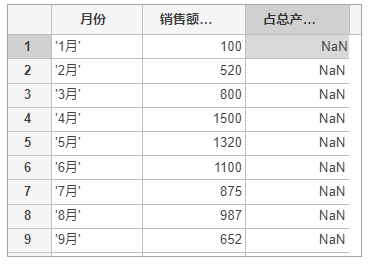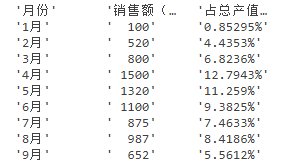

clear;clf;
A = readtable("src\data.xlsx","VariableNamingRule","preserve")

A = 13×3 table
        月份         销售额（万元）    占总产值百分比
    _____________    ____________    ____________

    {'1月'      }         100            NaN     
    {'2月'      }         520            NaN     
    {'3月'      }         800            NaN     
    {'4月'      }        1500            NaN     
    {'5月'      }        1320            NaN     
    {'6月'      }        1100            NaN     
    {'7月'      }         875            NaN     
    {'8月'      }         987            NaN     
    {'9月'      }         652            NaN     
    {'10月'     }        1300            NaN     
    {'11月'     }        1600            NaN     
    {'12月'     }         970            NaN     
    {'销售总额：'}       11724            NaN     


all = A.("销售额（万元）")(13);
A.("占总产值百分比") = num2str(A.("销售额（万元）") / all * 100) + "%";
disp(A)

        月份         销售额（万元）    占总产值百分比
    _____________    ____________    ____________

    {'1月'      }         100        "0.8529512%"
    {'2月'      }         520        " 4.435346%"
    {'3月'      }         800        "  6.82361%"
    {'4月'      }        1500        " 12.79427%"
    {'5月'      }        1320        " 11.25896%"
    {'6月'      }        1100        " 9.382463%"
    {'7月'      }         875        " 7.463323%"
    {'8月'      }         987        " 8.418628%"
    {'9月'      }         652        " 5.561242%"
    {'10月'     }        1300        " 11.08837%"
    {'11月'     }        1600        " 13.64722%"
    {'12月'     }         970        " 8.273627%"
    {'销售总额：'}       11724        "      100%"



(16 points)7.

a.load *picture.jpg* and display this picture 

加载图片文件（*picture.jpg*）并显示

clear;clf;
A = imread("src\picture.jpg");
imshow(A);

b. load *TheySay.mp3*, sound  and display sampling frequency. (Hint:What is the sampling frequency? Search on the Internet)

载入声音文件（*TheySay.mp3*），播放并输出采样频率

clear;clf;
[audio,Fs] = audioread("src\TheySay.mp3");
sound(audio,Fs);

         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0   

disp(Fs);